clear; clc; close all;

## Table obtention (Preparing)

opts = detectImportOptions('api_measurements/measurement_aircraft_10.csv');
timeTable = table();

temp = readtable("api_measurements/measurement_aircraft_10.csv",opts);
timeTable.m10 = temp.Var1;

temp = readtable("api_measurements/measurement_aircraft_50.csv",opts);
timeTable.m50 = temp.Var1;

temp = readtable("api_measurements/measurement_aircraft_100.csv",opts);
timeTable.m100 = temp.Var1;

temp = readtable("api_measurements/measurement_aircraft_500.csv",opts);
timeTable.m500 = temp.Var1;

temp = readtable("api_measurements/measurement_aircraft_1000.csv",opts);
timeTable.m1000 = temp.Var1;

temp = readtable("api_measurements/measurement_aircraft_5000.csv",opts);
timeTable.m5000 = temp.Var1;

temp = readtable("api_measurements/measurement_aircraft_10000.csv",opts);
timeTable.m10000 = temp.Var1;

statsTable = varfun(@(x) [mean(x); std(x); quantile(x,0.01); quantile(x,0.25); quantile(x,0.5); quantile(x,0.75); quantile(x,0.99)], ...
    timeTable);

statsTable.Properties.RowNames = {'mean' 'std' '1%' '25%' '50%' '75%' '99%'};
statsTable.Properties.VariableNames = extractAfter(statsTable.Properties.VariableNames,'Fun_');

statsArray = table2array(statsTable); statsArray = statsArray';

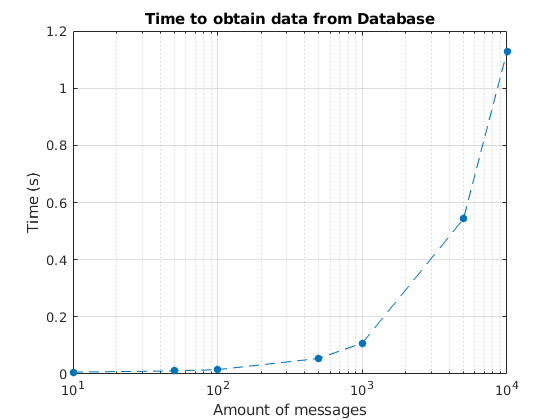

figure();
semilogx([10,50,100,500,1000,5000,10000],statsArray(:,1),'.--','MarkerSize',20);
grid on;
title('Time to obtain data from Database');
xlabel('Amount of messages');
ylabel('Time (s)');

statsArray = round(statsArray*1e5)/1e5;
statsTable = array2table(statsArray);
statsTable.Properties.VariableNames = {'\mu' '\sigma' '1%' '25%' '50%' '75%' '99%'};
statsTable.Properties.RowNames = {'10','50','100','500','1000','5000','10000'};
writetable(statsTable,'api_measurements/measurement_aircraft_stats.csv');

### Time (Data formation)

opts = detectImportOptions('api_measurements/measurement_preparation_10.csv');
timeTable = table();

temp = readtable("api_measurements/measurement_preparation_10.csv",opts);
timeTable.m10 = temp.Var1(1:100);

temp = readtable("api_measurements/measurement_preparation_50.csv",opts);
timeTable.m50 = temp.Var1(1:100);

temp = readtable("api_measurements/measurement_preparation_100.csv",opts);
timeTable.m100 = temp.Var1(1:100);

temp = readtable("api_measurements/measurement_preparation_500.csv",opts);
timeTable.m500 = temp.Var1;

temp = readtable("api_measurements/measurement_preparation_1000.csv",opts);
timeTable.m1000 = temp.Var1;

temp = readtable("api_measurements/measurement_preparation_5000.csv",opts);
timeTable.m5000 = temp.Var1;

temp = readtable("api_measurements/measurement_preparation_10000.csv",opts);
timeTable.m10000 = temp.Var1;

statsTable = varfun(@(x) [mean(x); std(x); quantile(x,0.01); quantile(x,0.25); quantile(x,0.5); quantile(x,0.75); quantile(x,0.99)], ...
    timeTable);

statsTable.Properties.RowNames = {'mean' 'std' '1%' '25%' '50%' '75%' '99%'};
statsTable.Properties.VariableNames = extractAfter(statsTable.Properties.VariableNames,'Fun_');

statsArray = table2array(statsTable); statsArray = statsArray';

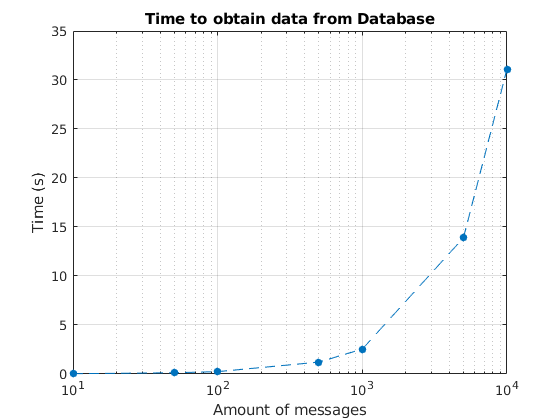

figure();
semilogx([10,50,100,500,1000,5000,10000],statsArray(:,1),'.--','MarkerSize',20);
grid on;
title('Time to obtain data from Database');
xlabel('Amount of messages');
ylabel('Time (s)');

statsArray = round(statsArray*1e5)/1e5;
statsTable = array2table(statsArray);
statsTable.Properties.VariableNames = {'\mu' '\sigma' '1%' '25%' '50%' '75%' '99%'};
statsTable.Properties.RowNames = {'10','50','100','500','1000','5000','10000'};
writetable(statsTable,'api_measurements/measurement_preparation_stats.csv');

statsArray2 = statsArray * 5 + rand(size(statsArray));
statsArray2 = round(statsArray2*1e5)/1e5;
statsTable2 = array2table(statsArray2);
statsTable2.Properties.VariableNames = {'\mu' '\sigma' '1%' '25%' '50%' '75%' '99%'};
statsTable2.Properties.RowNames = {'10','50','100','500','1000','5000','10000'};
writetable(statsTable2,'api_measurements/measurement_tdoa_stats.csv');